# 导入电子表格中的数据

用于从以下电子表格导入数据的脚本:

由 MATLAB 于 2023-06-04 22:28:04 自动生成

## 设置导入选项并导入数据

opts = spreadsheetImportOptions("NumVariables", 9);

% 指定工作表和范围
opts.Sheet = "Sheet1";
opts.DataRange = "A4:I34";

% 指定列名称和类型
opts.VariableNames = ["Var1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9"];
opts.SelectedVariableNames = ["VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9"];
opts.VariableTypes = ["char", "double", "double", "double", "double", "double", "double", "double", "double"];

% 指定变量属性
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto");

% 导入数据
data21 = readmatrix("B:\360MoveData\Users\15711\Desktop\tempFile\数据分析\data21.xls", opts, "UseExcel", false);

consumptionData=zscore(data21);
% 导入数据
[~, txt] = xlsread('data21.xls');
% 提取地区名称
regionNames = txt(4:end, 1);
%1. 主成分分析
[coeff,score,latent] = pca(consumptionData);

% 给出各主成分的贡献率
contributionRate = latent ./ sum(latent);

disp('贡献率:');

贡献率:


disp(contributionRate);

    0.8581
    0.0719
    0.0211
    0.0181
    0.0124
    0.0105
    0.0054
    0.0026




%2. 分析前两个主成分的意义，并按第一主成分得分将31个省、市、自治区和直辖市排序
% 主成分得分
firstPCAScore = score(:, 1);
secondPCAScore = score(:, 2);

% 按第一主成分得分排序
[~, sortIndex] = sort(firstPCAScore, 'descend');

disp('Regions sorted by first PCA score:');

Regions sorted by first PCA score:


disp(regionNames(sortIndex));

    {' 上  海'}
    {' 北  京'}
    {' 浙  江'}
    {' 江  苏'}
    {' 福  建'}
    {' 广  东'}
    {' 山  东'}
    {' 辽  宁'}
    {' 天  津'}
    {' 内蒙古' }
    {' 吉  林'}
    {' 黑龙江' }
    {' 湖  南'}
    {' 湖  北'}
    {' 山  西'}
    {' 河  北'}
    {' 江  西'}
    {' 河  南'}
    {' 安  徽'}
    {' 宁  夏'}
    {' 陕  西'}
    {' 四  川'}
    {' 青  海'}
    {' 新  疆'}
    {' 广  西'}
    {' 重  庆'}
    {' 云  南'}
    {' 海  南'}
    {' 西  藏'}
    {' 甘  肃'}
    {' 贵  州'}



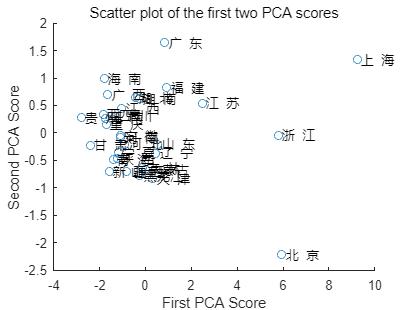


%3. 画出前两个主成分得分的散点图，并在散点图上标注上各个地区的名称
figure;
scatter(firstPCAScore, secondPCAScore);
text(firstPCAScore, secondPCAScore, regionNames, 'HorizontalAlignment', 'left');
xlabel('First PCA Score');
ylabel('Second PCA Score');
title('Scatter plot of the first two PCA scores');

## 清除临时变量

clear opts